This function provides the state equation for the simple planarvehicle model. It includes the longitudinal tire deflections and dynamic braking

torques generated by a three-point controller

function [xdot , out] = fun_08_abs_brake_dyn(t ,x , p) 

% get states 
posx = x(1); posz = x(2); pitch = x(3); % Vehicle position & oriantation 
velx = x(4); velz = x(5); pdot = x(6);  % Vehicle velocities
O = x(7:8);                             % angular velocities of front & rear wheels
xt = x(9:10);                           % longitudinal tyre deflection front & rear wheels
tqbctrl = x(11:12);                     % controlled braking torques on front & rear wheels

% Wheels loads(linear suspension force characteristics) 
out.fz = [p.fz0(1) - p.cs1 * (posz - p.a1 * pitch) - p.ds1 * (velz - p.a1 * pdot);
    p.fz0(2) -p.cs2 * (posz + p.a2 * pitch) - p.ds2 * (velz + p.a2 * pdot) ];

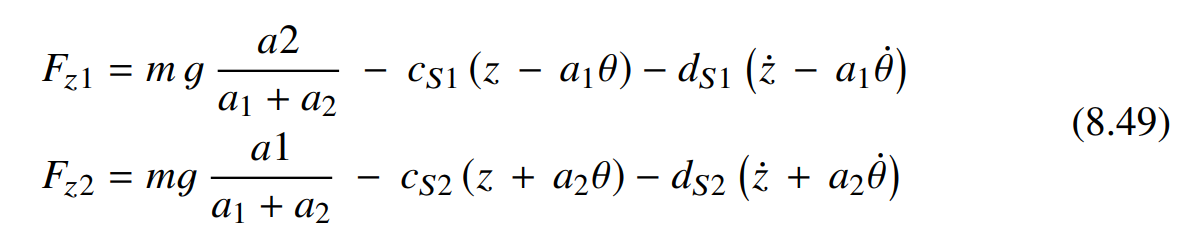   

The linear suspension model realized in Equation (8.49) delivers the wheel loads o.fz, where the elements  p.fz0(1) and p.fz0(2) of the parameter structure provide their steady-state values.

% get maximum braking torque via linear interpolation & default 
tqb_mx = interp1(p.tqb_t , tqb_v , t) ;
out.TB = [0;0];

% tyre and wheel dynamics : front wheel (i=1) , rear wheel (i =2)
xtdot =[0;0]; Odot =[0;0] ;  fos = [0;0]; out.fx =[0;0]; fosm =[0;0]; wf =[0;0]; % weighting factor
for i = 1:2
    % modified transport velocities and long . slips
    vc = p.r *O(i); vt = abs(vc) ; vtn = vt + p.vn; vs = (velx - vc); out.sx(i) = -vs / vtn ; sc = abs(out.sx(i));
    % simple linear wheel load influence to tyre parameter
    wf(i) = out.fz(i) / p.fzn; fosm(i) = p.fxm / p.sxm * wf(i);
    pt = [p.dfx0 * wf(i) , p.fxm * wf(i), p.sxm , p.fxs * wf(i) , p.sxs];
    % generalized tyre characteristics (sx only)
    [~,fos(i)] = tmy_fcombined(sc , pt(1) , pt(2) , pt(3) , pt(4) , pt(5));
    % time drivative of long.tyre deflection & long. dynamic tyre force
    xtdot(i) = -(p.cx * xt(i) * vtn + fos(i) * vs) / (p.dx * vtn + fos(i));

out.fx(i) = p.cx * xt(i) + p.dx * xtdot(i);
% applied braking torque (Enhanced dry friction model)
out.TB(i) = -p.r0 * out.fx(i) + p.dn * O(i);
out.TB(i) = sign(out.TB(i)) * min(abs(out.TB(i)) , max(0 , tqbctrl(i)));

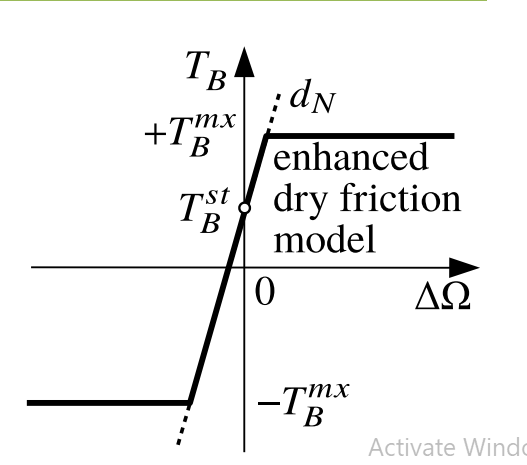 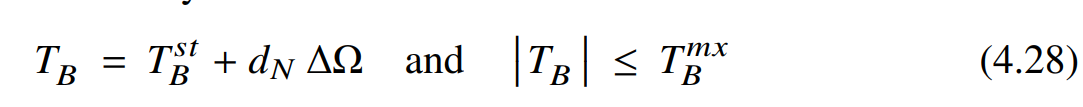

% angular momentum wheel (no driving torque)
Odot(i) = (-out.TB(i) - p.r0 * out.fx(i)) / p.thetaW ;

 

end

The loop from line 19 to 35  computes at first the global derivatives fos(i) of the longitudinal tire characteristics via the function tmy_fcombined which

is provided by Listing 3.3. Note, that the initial inclination, the maximum, and the sliding force provided by the elements  p.dfx0, p.fxm, and p.fxs of the parameter

structure, are adjusted by the weighting factor  wf(i)=o.fz(i)/p.fzn to the actual wheel loads. Then, the dynamic tire forces  o.fx(i) are calculated and the enhanced

braking torque model delivers the required braking torques  o.tqba(i) at the wheels. Finally, the wheel accelerations 

owhdot(i) are computed, where the state variables tqbctrl(i) represent the controlled braking torques at the front (i=1) and the rear wheel (i=2)  

% vehicle eqn. of motion: Long. , vertical & pitch

velxdot = (out.fx(1) + out.fx(2)) / p.mass ;
velzdot = (out.fz(1) + out.fz(2)) / p.mass -p.gravity ;
pdotdot = (- p.a1 * fz(1) + p.a2 * fz(2) - (out.fx(1) + out.fx(2)) * p.h) / p.theta ; 

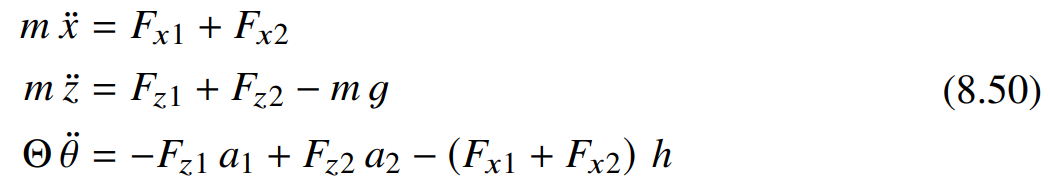 

# the maximum possible tire/road friction coefficient: 

% ABS like control ( simple 3 - point brake torque control ) 
tqbctrldot = [0 , 0] ; Odx = 1.2 * p.gravity / p.r0 ;   % " hold " & max . wheel decel 

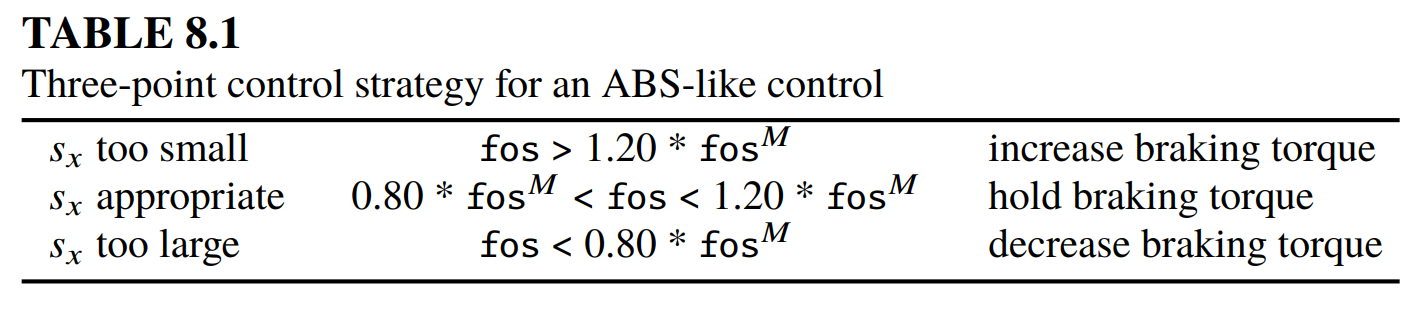 

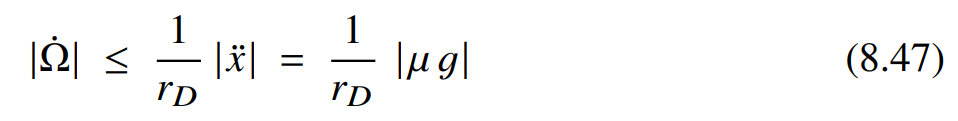   

for i = 1:2
 % "increase torque"
 if fos(i) > 1.2 * fosm(i) && tqbctrl(i) < tqb_mx && abs(odot(i)) < odx 
     tqbctrldot(i) = p.tqb_inc * abs(velx) / (abs(velx) + 1);
 end
 % "decrease torque"
 if fos(i) < 0.8 * fosm(i) && tqbctrl(i) > 0.0
     tqbctrldot(i) = - p.tqb_dec * abs(velx) / (abs(velx) + p.vn);
 end
end

#### The simple three-point control just distinguishes between increase, hold, and

#### decrease. The increase and decrease conditions, shown in Table 8.1 are supplemented

#### by practical restrictions, that the controlled braking torque is limited to the provided

#### maximum braking torque and must be positive according to the definition used here.

#### In addition, the condition for torque increase takes Equation (8.47) into account,

#### whereby the maximum possible tire/road friction coefficient was roughly estimated by µ = 1:2.

#### By multiplying the braking torque changes  tqbctrldot(i) at the front (i=1) and the rear wheel (i=2) with the term abs(velx)/(abs(velx)+1.0), the changes in the braking torques become less intensive, as done in practice, when the vehicle comes close to a standstill  velx ! 0.  

% state derivatives (vehicle , wheel , tyre , braking torque) 
xdot = [ velx ; velz ; pdot ; velxdot ; velzdot ; pdotdot ; Odot ; xtdot ; tqbctrldot ] ;
end